**Summary**

Log Log Plots are produced of the error $\delta I\left(n\right)$ as a function of the number n of gridpoints.

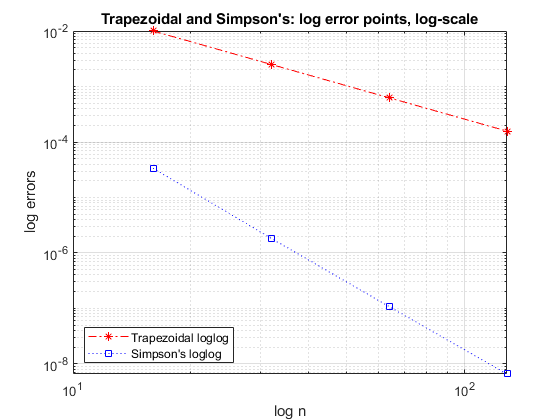

n_i = [16, 32, 64, 128];
n_N = length(n_i);
start = 0;
finish = pi;

for j = 1: n_N
    y_trap_err(j)= (TrapError(n_i(j),start,finish));
    y_simp_err(j) = (SimpError(n_i(j)-1,start,finish));  
end

loglog(n_i,y_trap_err, '-.r*',n_i,y_simp_err, ':bs');
x_log = log(n_i);
ylabel([{'log errors'}]);
xlabel([{'log n'}]);
legend("Trapezoidal loglog","Simpson's loglog", 'Location', 'southwest')
title("Trapezoidal and Simpson's: log error points, log-scale")
grid on;